## Datos de cinética de reacción

Supongamos que A y B reaccionan para formar C y, a medida que ocurre esta reacción, cambia el color. Al mantener constante la concentración de A y variar la concentración de B y la temperatura, medimos cuánto tiempo tarda en observarse el cambio de color. Este tipo de cinética de reacción podría utilizarse en el mecanismo de detención de un Chem-E-Car.

Reacción química:


$$A+B\to C$$


Capturamos nuestros datos de cinética de reacción en hojas de cálculo de Excel.

## Cargar datos de cinética de reacción

Después de importar los datos utilizando el botón "**Import Data**" en la barra de herramientas de MATLAB para la hoja de cálculo seleccionada, genera automáticamente una función usando el menú desplegable "**Import Selection**", luego "**Generate Function**" y llama a esta función para importar los datos.

rxn_data = readtable("rxn_data.xlsx")

## Visualizar datos de cinética de reacción

Después de importar los datos, podemos visualizar los datos de tiempo vs. concentración como un diagrama de dispersión para las diferentes temperaturas usando una **Task ** (en la pestaña LIVE EDITOR) llamada **Create Plot **

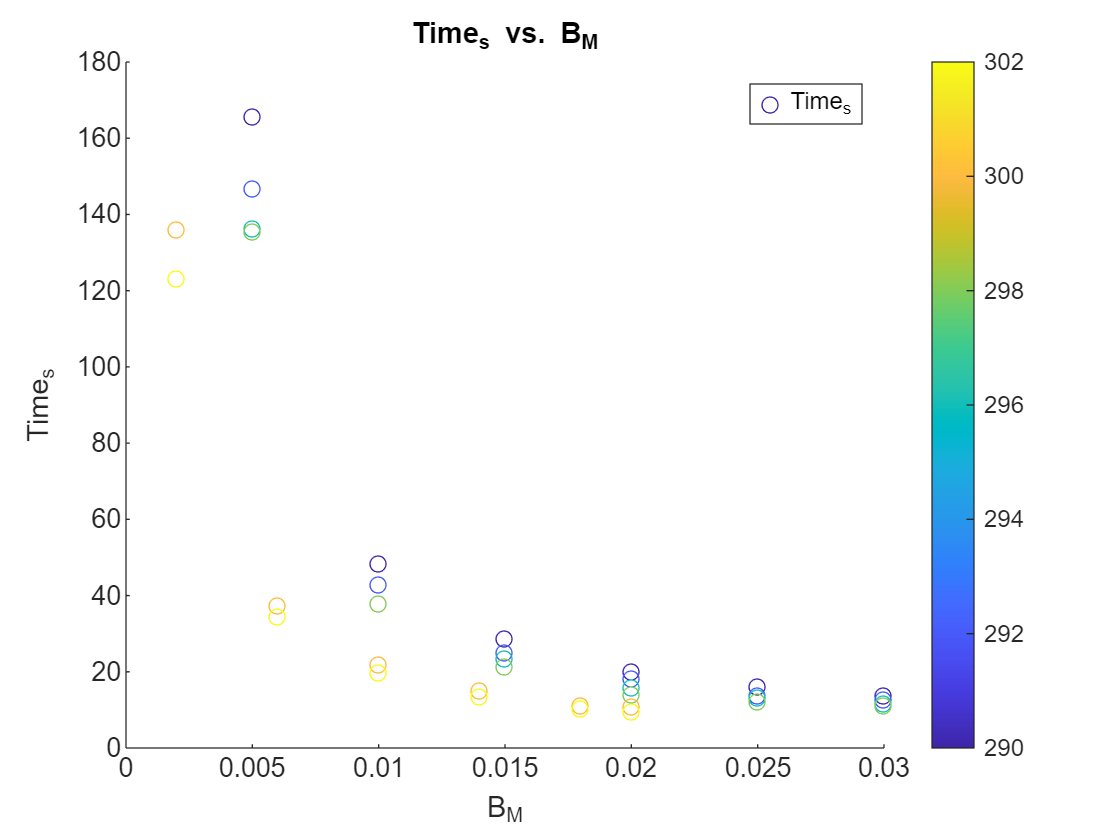

% Create scatter of selected data
s = scatter(rxn_data,"B_M","Time_s","ColorVariable","Temperature_K","DisplayName","Time_s");

% Add xlabel, ylabel, title, and legend
xlabel("B_M")
ylabel("Time_s")
title("Time_s vs. B_M")
legend

colorbar

list_temperatures = unique(rxn_data.Temperature_K);
idx = rxn_data.Temperature_K == list_temperatures(2);
data_selected = rxn_data(idx,:);

## Ajuste de curvas a datos de cinética de reacción

Con la aplicación "**Curve Fitter**" puedes hacer un ajuste de las ecuaciones a los datos. Puedes encontrarla en la pestaña APPS (esta aplicación forma parte del Curve Fitting Toolbox; si no aparece en la pestaña "APPS", puedes agregarla mediante "Add-Ons" en la pestaña HOME). También puedes explorar diversas relaciones de forma interactiva con esta herramienta. En este caso, ajustamos una relación exponencial asignando los datos de concentración de la sustancia química B a la variable "x" y los datos de tiempo a la variable "y".

fprintf('La gráfica muestra datos para %d K',data_selected.Temperature_K(1) )

La gráfica muestra datos para 292 K

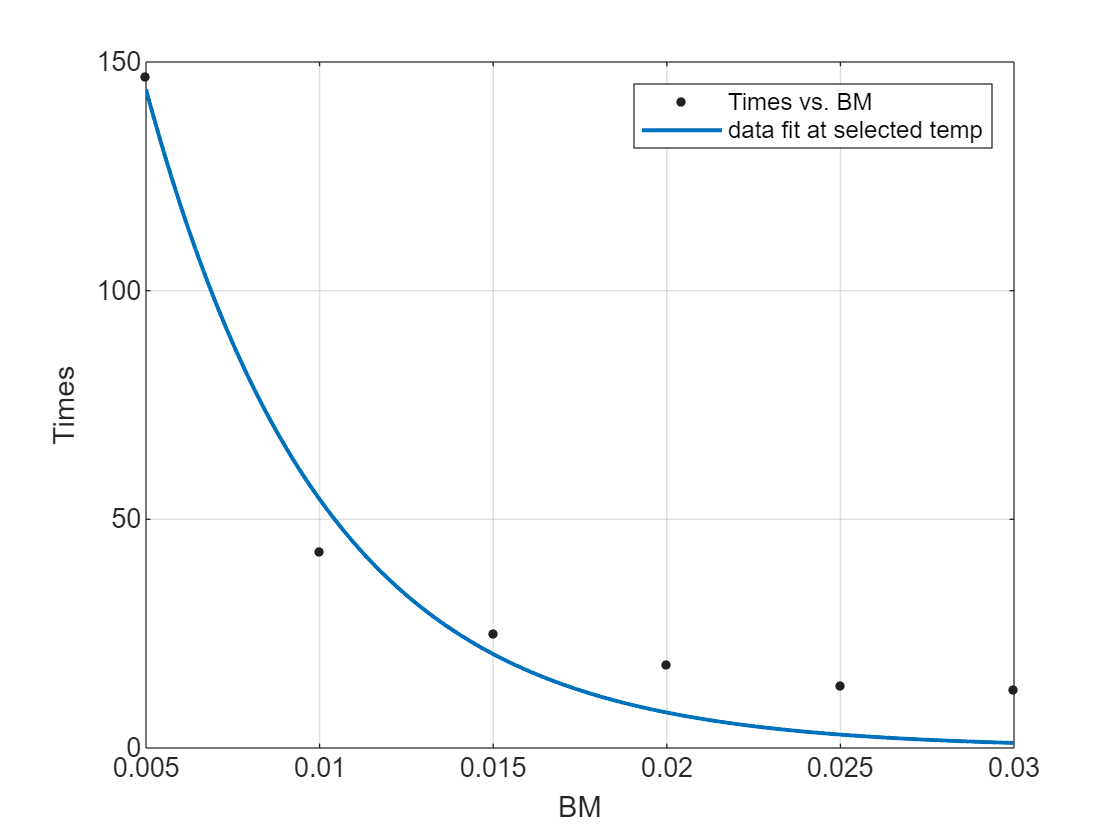

fitresult =      General model Exp1:
     fitresult(x) = a*exp(b*x)
     Coefficients (with 95% confidence bounds):
       a =       381.3  (161.2, 601.3)
       b =      -194.7  (-287.3, -102.1)

gof = struct with fields:
           sse: 521.2363
       rsquare: 0.9613
           dfe: 4
    adjrsquare: 0.9517
          rmse: 11.4153

[fitresult, gof] = createFit(data_selected.B_M, data_selected.Time_s)

También puedes ajustar curvas a los datos recopilados a otras temperaturas usando la misma app.

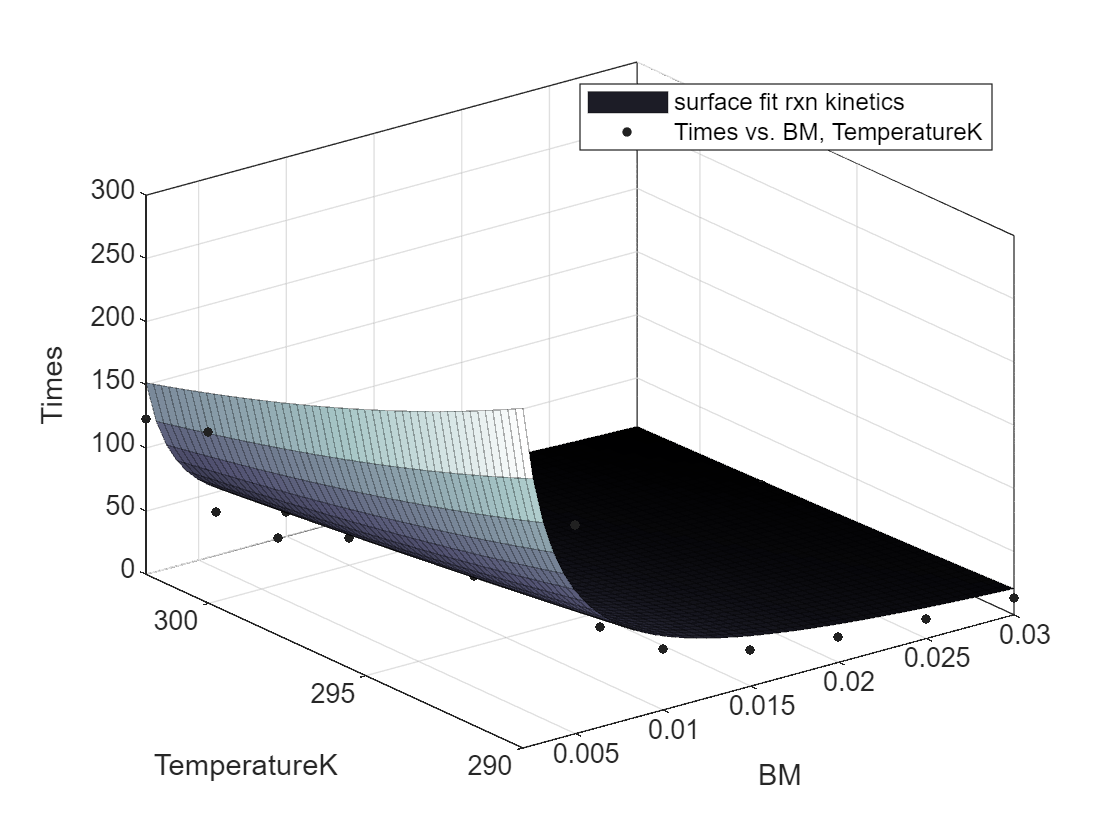

surffitresult =      General model:
     surffitresult(x,y) = a*exp(-b/y)*(x^c)
     Coefficients (with 95% confidence bounds):
       a =   4.085e-07  (-4.092e-06, 4.909e-06)
       b =       -4180  (-7246, -1115)
       c =     -0.9478  (-1.156, -0.7398)

surfgof = struct with fields:
           sse: 1.5534e+04
       rsquare: 0.7964
           dfe: 33
    adjrsquare: 0.7841
          rmse: 21.6961

[surffitresult, surfgof] = createSurfaceFit(rxn_data.B_M, rxn_data.Temperature_K, rxn_data.Time_s)

## ¿Cómo recopilar datos sistemáticamente?

- [Diseño de experimentos](https://www.mathworks.com/help/stats/design-of-experiments-1.html)

## Otros materiales

- [Chem-E-Car Competition resources](https://www.mathworks.com/academia/student-competitions/aiche-chem-e-car.html)

- [MATLAB Academy](https://matlabacademy.mathworks.com/?page=1&sort=featured)

## References

[1] [CHEM-E-CAR: IODINE CLOCK REACTION, Guillermo Díaz Sainz, 2015](https://repositorio.unican.es/xmlui/bitstream/handle/10902/6696/376369.pdf?sequence=1)